buildingDir = uigetdir("Title","Please select the folder to read the rGUV tiff files.");
buildingScene = imageDatastore(buildingDir);

%% make a folder to save the masked_cropped_adapthisteq tiff
saveDir = replace(buildingDir, "/RGB_overlay", "/panoramas"); % works if suffix is exactly "/cam0" 
if ~isfolder(saveDir)
    mkdir(saveDir);
end

%% read and sort files
files = buildingScene.Files;

% Match RGB index from filename RGB_<n>.tiff
tokens = regexp(files, 'RGB_([0-9]{1,3})\.tiff?$', 'tokens', 'once');

nums = nan(size(tokens));
for k = 1:numel(tokens)
    if ~isempty(tokens{k})
        nums(k) = str2double(tokens{k}{1});
    end
end

% /left should stitch right->left: use descending index so largest TIFF is fixed image.
if contains(buildingDir, '/left')
    sortDir = 'descend';
else
    % /right (and default) keep original left->right ordering.
    sortDir = 'ascend';
end

[~, order] = sort(nums, sortDir, 'MissingPlacement', 'last');

% Reorder datastore (replace Files)
buildingScene.Files = files(order);
numFiles = numel(buildingScene.Files);

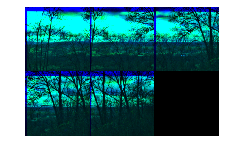

montage(buildingScene.Files)

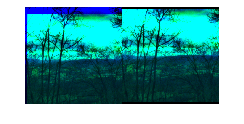

I = crop_pano_to_largest_valid_rect(imread(buildingScene.Files{1})); % crop out the single-channel part (happened during homography)
grayImage = im2gray(I);
montage({imread(buildingScene.Files{1}),I});

% Preallocate container for grayscale images as a cell array (images can be different sizes)
numImages = numel(buildingScene.Files);
grayImages = cell(numImages,1);
grayImages{1} = grayImage;

points = detectSURFFeatures(grayImages{1});
[features,points] = extractFeatures(grayImages{1},points);

%%
tforms(numImages) = projtform2d;
imageSize = zeros(numImages,3);
imageSize(1,:) = size(I);

%%
for n = 2:numImages
    pointsPrevious = points;
    featuresPrevious = features;
        
    I_full = readimage(buildingScene, n);
    I=crop_pano_to_largest_valid_rect(I_full);
    grayImages{n} = im2gray(I);
    imageSize(n,:) = size(I);
    
    points = detectSURFFeatures(grayImages{n});
    [features,points] = extractFeatures(grayImages{n},points);
  
    indexPairs = matchFeatures(features,featuresPrevious,Unique=true);
    matchedPoints = points(indexPairs(:,1), :);
    matchedPointsPrev = pointsPrevious(indexPairs(:,2), :);        
    
    tforms(n) = estgeotform2d(matchedPoints, matchedPointsPrev,...
        "projective",Confidence=99.9,MaxNumTrials=2000);
    
    tforms(n).A = tforms(n-1).A * tforms(n).A; 
end

%%
% Compute output limits for each transform. imageSize is Nx3 (H W 3), so use
% the first two columns for height and width.
for idx = 1:numel(tforms)
    height_i = imageSize(idx,1);
    width_i  = imageSize(idx,2);
    [xlim(idx,:), ylim(idx,:)] = outputLimits(tforms(idx), [1 width_i], [1 height_i]);
end

%%
avgXLim = mean(xlim, 2);
[~,idx] = sort(avgXLim);
centerIdx = floor((numel(tforms)+1)/2);
centerImageIdx = idx(centerIdx);

%%
Tinv = invert(tforms(centerImageIdx));
for idx = 1:numel(tforms)
    tforms(idx).A = Tinv.A * tforms(idx).A;
end

%%
% Recompute output limits after normalizing to the center transform
for idx = 1:numel(tforms)
    height_i = imageSize(idx,1);
    width_i  = imageSize(idx,2);
    [xlim(idx,:), ylim(idx,:)] = outputLimits(tforms(idx), [1 width_i], [1 height_i]);
end
maxImageSize = max(imageSize(:,1:2), [], 1); % [maxHeight, maxWidth]

%%
xMin = min([1; xlim(:)]);
xMax = max([maxImageSize(2); xlim(:)]); % use max width

yMin = min([1; ylim(:)]);
yMax = max([maxImageSize(1); ylim(:)]); % use max height
width  = round(xMax - xMin);
height = round(yMax - yMin);

%%
xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width],xLimits,yLimits);

%% 
panorama = zeros([height width 3],"like",I);
for idx = 1:numImages
    I_full = readimage(buildingScene,idx);   
    I = crop_pano_to_largest_valid_rect(I_full);
    warpedImage = imwarp(I,tforms(idx),OutputView=panoramaView);                 
    mask = imwarp(true(size(I,1),size(I,2)),tforms(idx),OutputView=panoramaView);
    panorama = imblend(warpedImage,panorama,mask,foregroundopacity=1);
end

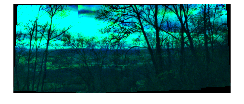

imshow(panorama)

imwrite(panorama, fullfile(saveDir, sprintf('panorama_scriptGen_l_GUV.tiff')));